# **Tutorial 8**: a spacecraft with 2 symmetrical rotating solar arrays defined by a generic plate model ( run $\le 1\;mn$).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

This tutorial reconsiders the same example already addressed in the  [tutorial 2](matlab:open('../Tutorial2/tutorial2.html')) and  [tutorial 4](matlab:open('../Tutorial4/tutorial4.html')) (of the **full version** of the `SDTlib`) but the models $[\mathbf D_{A_i}^{\mathcal{A}_i}]_{\mathcal R_{a_i}}(\mathrm s)$, ($i=1,2$) of 2 the rotating solar flexible solar arrays are now defined by:

- a generic rectangular uniform plate for each solar array $\mathcal A_i$,

- a revolue joint at the connection point $P_i$.

## 2. Plate model

During early preliminary design phase, the user could not know:

- neither the flexible mode characteristics (frequencies, modal participation factors, ...) required to fill the dialog box of the block `1 port flexible body,`

- nor the NASTAN model required to fill the dialog box of the blocks  or `1 port Natran body` or `N ports Nastran body `(of the **full version** of the `SDTlib`)

to model the solar panels.

To address this situation, a generic *Kirchhoff-love* model of a uniform rectangular plate was developped. This model involves $18$ flexible modes per plate.

This model is implemented in the block` multi-port flexible plate` of the **SDTlib/**`6 dof bodies` sub-library. The dialog box (depicted in the following) requires only the geometric data of the plate and the material characteristics.

**WARNING**:** this block does not support varying or uncertain parameters but it is possible to take into account relative uncertainties on the first cantilevered frequencies**.

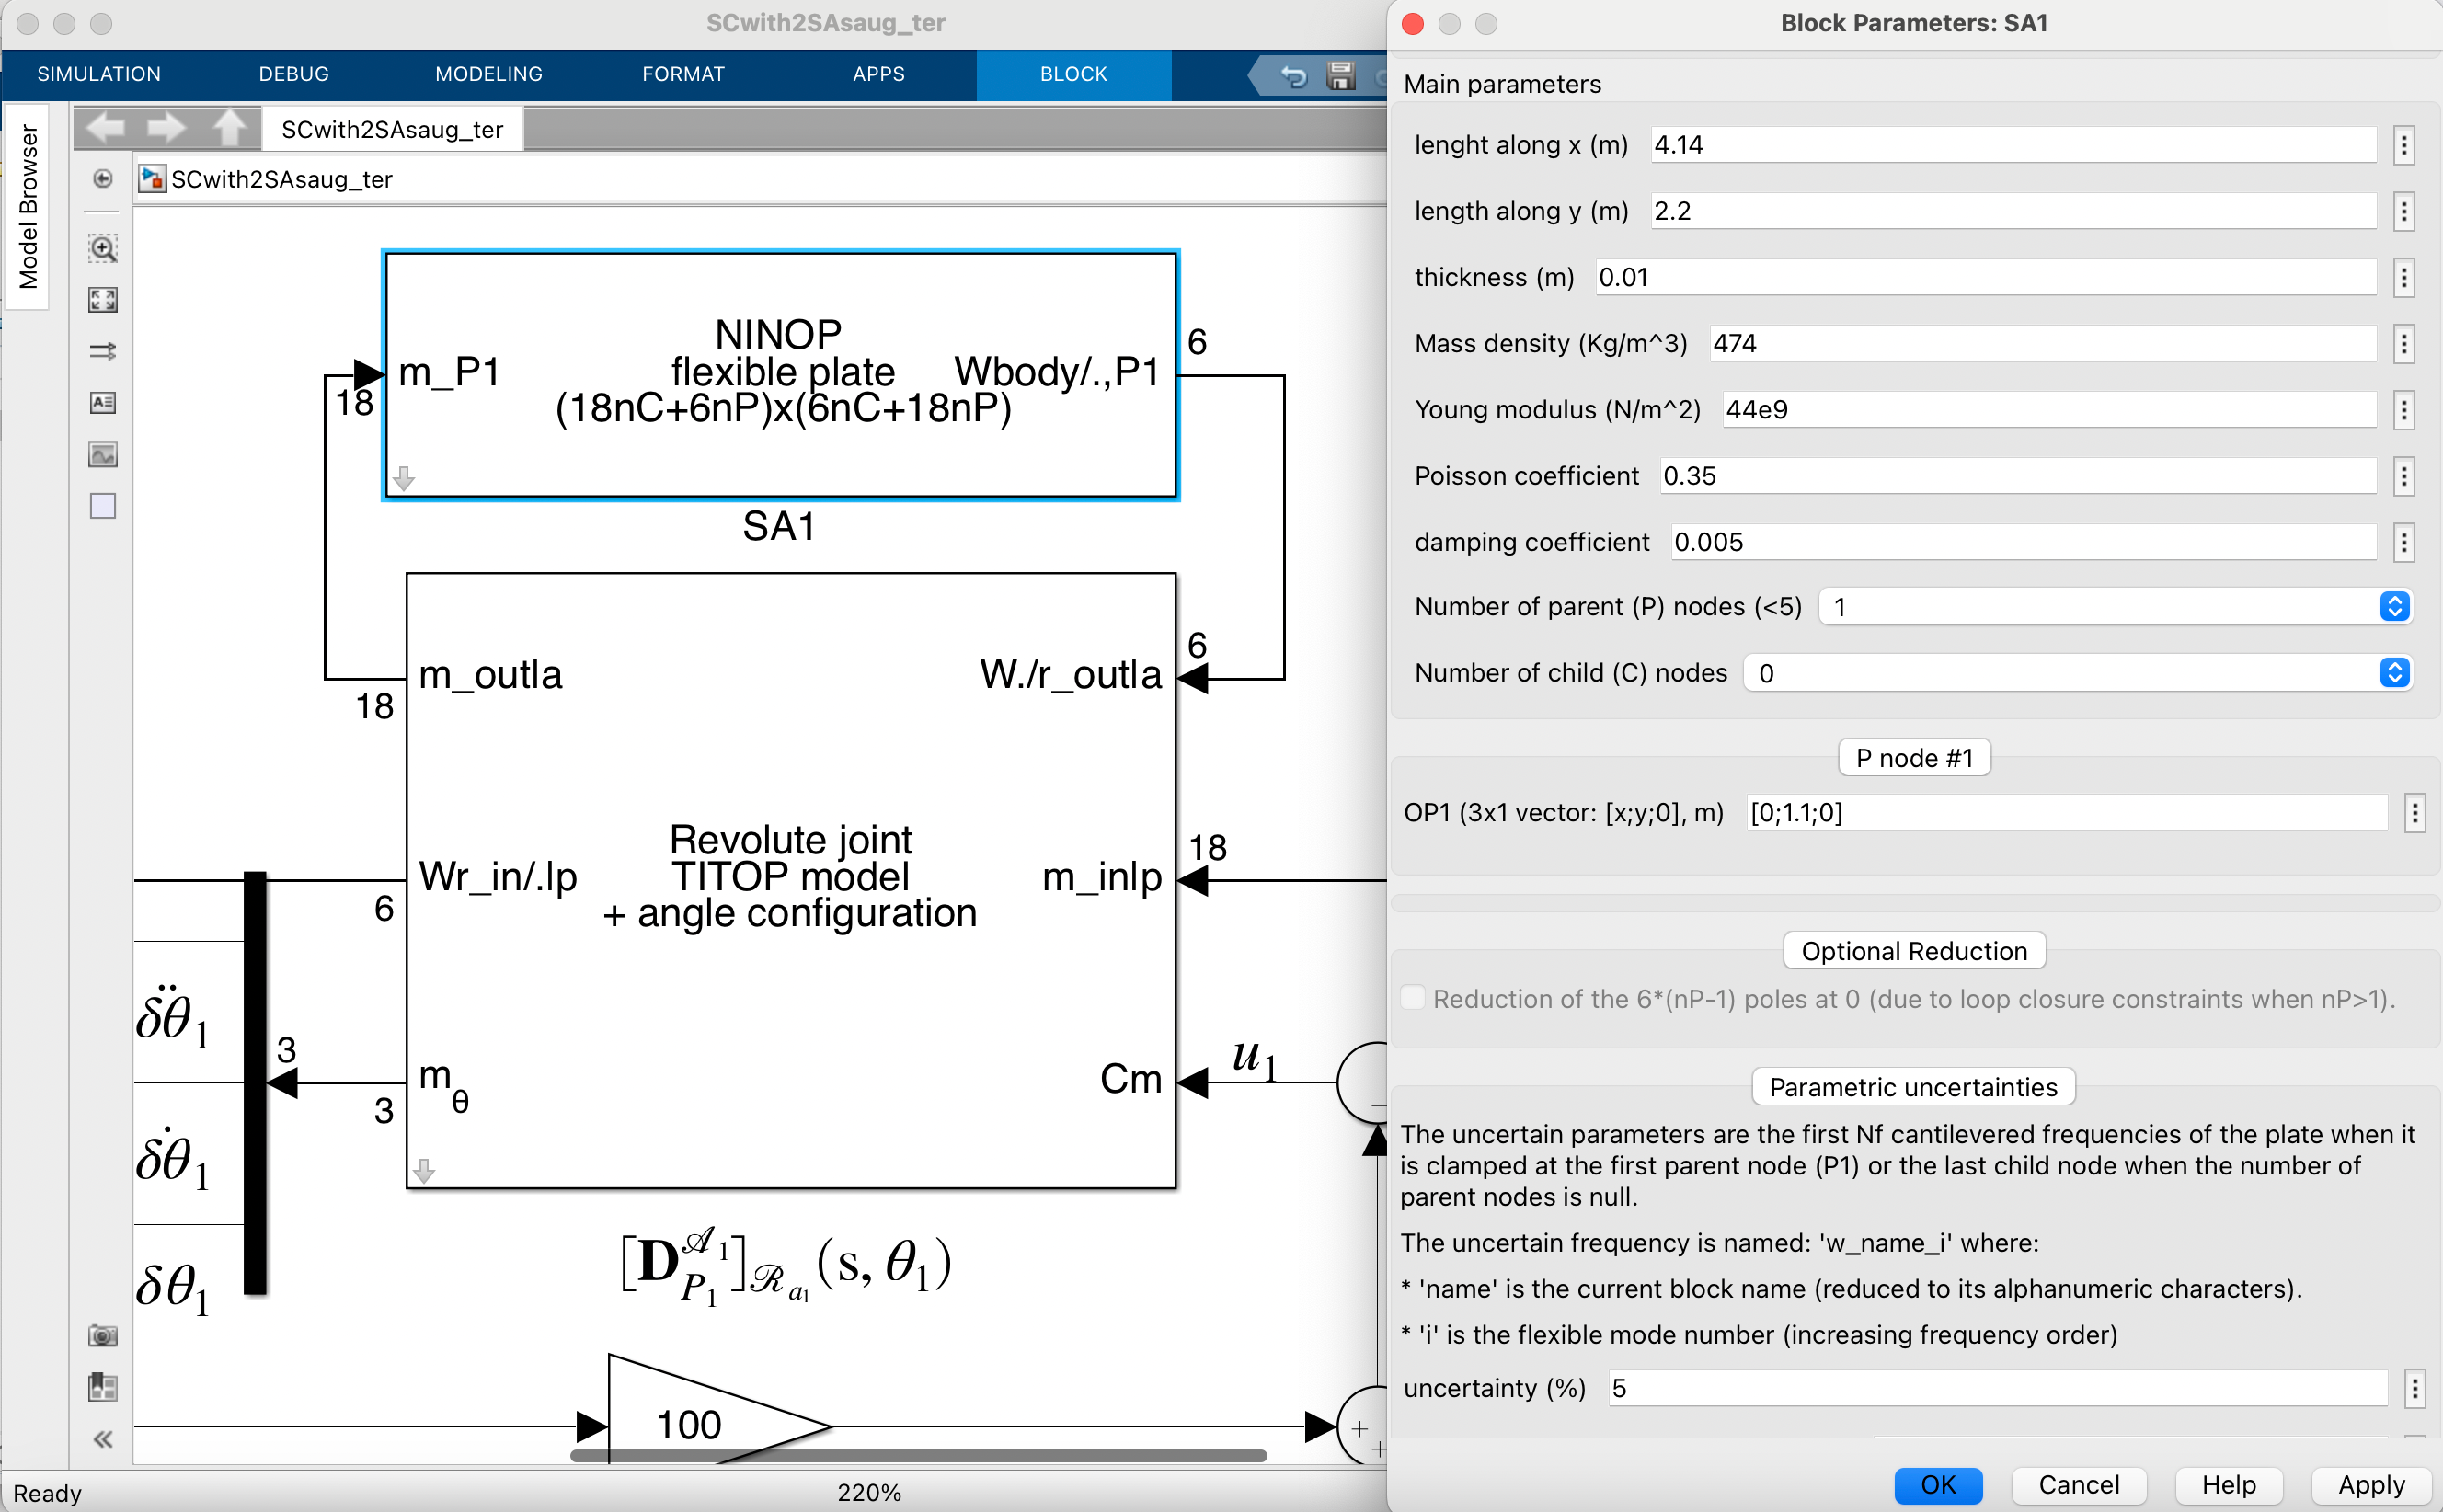

The reader is advised to read the inline help available in the dialog box (internet connection required) to have details on the *Kirchhoff-Love *model used for the flexible plate, also available by:

web DocPlate_joly.html -new

## 3. The whole  $6\times 8$ dynamic model

The whole model is then described by the following SIMULINK file `SCwith2SAs_ter.slx`:

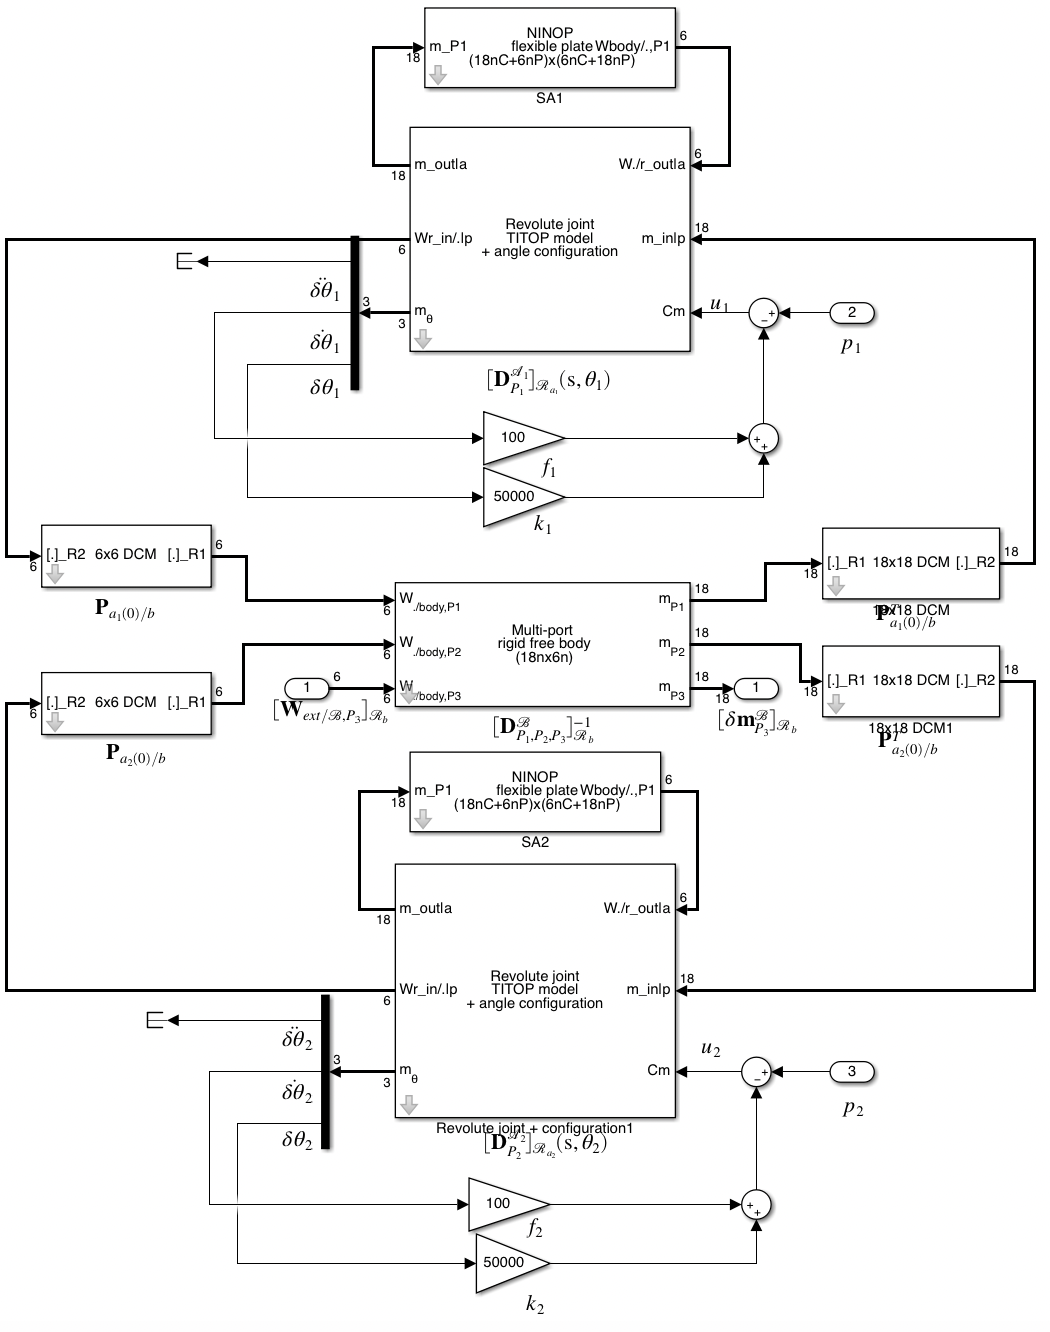

SCwith2SAsaug_ter                      % the SIMULINK lile of the model
Gu=ulinearize('SCwith2SAsaug_ter')

Gu =

  Uncertain continuous-time state-space model with 18 outputs, 8 inputs, 88 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences

Type "Gu.NominalValue" to see the nominal value, "get(Gu)" to see all properties, and "Gu.Uncertainty" to interact with the uncertain elements.



As in  [tutorial 2](matlab:open('../Tutorial2/tutorial2.html')), one can check that the model have 8 inputs:

- the external wrench $[\mathbf W_{ext/\mathcal B,B}]_{\mathcal R_b}$ (6 components)

- $p_1$ the torque disturbance inside the revolute joint of $\mathcal A_1$,

- $p_2$ the torque disturbance inside the revolute joint of $\mathcal A_2$,

18 outputs:  the [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html')) of point $B$ $[\delta\mathbf m^{\mathcal B}_{P_1}]_{\mathcal R_b}$ (18 components = 6 DoFs accelerations , 6 DoFs velocities and 6 DoFs positions),,

but $88$ states: $44$ modes (18 flexible modes + 1 revolute joint mode per appendage and 6 rigid modes of the main body).

This model depends on the uncertain parameter $\sigma_4=\tan\frac{\theta}{4}$ (`tan_Theta_div4`) with 32 occurences.

## 4. Analyses

As in [tutorial 2](matlab:open('../Tutorial2/tutorial2.html')), the same kind of analyses can be now performed on this new model, for instance  the frequency-domain response (Bode magnitude) of the $3\times 3$ transfer between the torque applied to the spacecraft at $B$ and its angular acceleration:

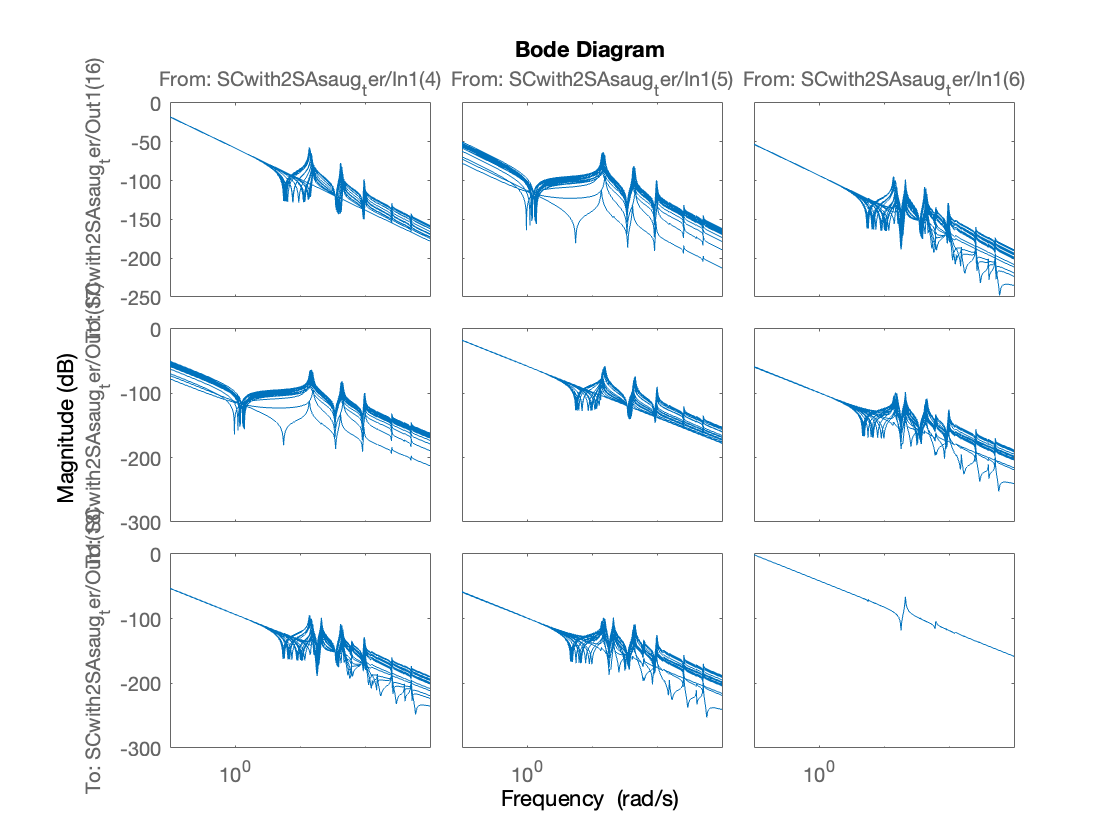

figure
bodemag(Gu(16:18,4:6),{0.1 1000})

## 5. Remark

- As the `N Ports Nastran body `block, this block can be used to build the model of an array of solar pannels by using additionnal ports to connect the various pannels (see also tutorial 9 of the** full version** of the `SDTlib`: [***a solar array with 3 pannels***](matlab:open('../Tutorial9/tutorial9.html'))).